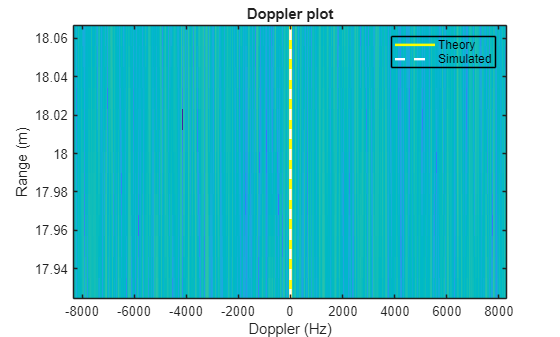

% ===========================================
% Modern Communications Systems
% Project
% Fall 2025
% FMCW Doppler Code
%  - Using phased.FMCWWaveform (Phased Array toolbox)
%  - Generate Range–Doppler map
%  - Modulated backscatterer (optional) 
% ---------------------------------------------------

clear; clc; close all;

%% Waveform parameters
c   = 3e8;
fc  = 77e9;           % Carrier [Hz]
B   = 1.6e9;          % Sweep bandwidth [Hz]
Ts  = 60e-6;          % Sweep time per chirp [s]
fs  = 8e6;            % Sample rate [Hz]
K   = 512;            % Number of chirps per frame [#]

waveform = phased.FMCWWaveform( ...
    'SweepTime', Ts, ...
    'SweepBandwidth', B, ...
    'SampleRate', fs, ...
    'SweepDirection', 'Up');

Ns  = round(Ts*fs);     % Samples per chirp
t   = (0:Ns-1)/fs;      % Fast time per chirp
Tch = Ts;               % PRI ≃ sweep time --> no idle here

% Scene --> one object (natural)
R0 = 18;                % Range [m]
v0 = 0;                 % Velocity [m/s]
SNRdB = 20;

useModulated = false;   % On/Off for modulated backscatter
fm_mod  = 1e3;          % Modulated frequency [Hz] (if activated)

% Derived tones
fb_obj = 2*B*R0/(c*Ts); % Range-induced beat frequency [Hz]
fD_obj = 2*fc*v0/c;     % Slow-time Doppler [Hz]

% Pre-allocate beats
rx_beats = zeros(Ns, K);

rng(7); % For reproducibility 
for k = 1:K
    
    % Calculate object beat for a chirp k
    phi_slow = 2*pi*fD_obj*(k-1)*Tch;             % slow-time phase advance
    rx_obj   = exp(1j*(2*pi*fb_obj*t + phi_slow));
    
    if useModulated
        % Modulated backscatter
        rx_mod = 0.6*exp(1j*(2*pi*fm_mod*(k-1)*Tch)) .* exp(1j*(2*pi*fb_obj*t));
        rx = rx_obj + rx_mod;
    else
        rx = rx_obj;
    end
    
    % Add noise to each chirp
    rx = rx + (randn(1,Ns)+1j*randn(1,Ns))*10^(-SNRdB/20)/sqrt(2);
    rx_beats(:,k) = rx(:);
end

% Range processing
Nrange = 4096;
WINr   = hann(Ns); % Hann window
RFFT   = fft(rx_beats.*WINr, Nrange, 1);         
Rmag   = abs(RFFT);

% Generate range axis
% Positive frequencies only --> otherwise get mirroring on the plot
f_axis  = (0:Nrange-1)'/Nrange*fs;      % [Hz]
rng_axis= f_axis * (c*Ts)/(2*B);        % [m]
[~, rng_bin] = max(mean(Rmag,2));       % Take average across slow time
Rdet = rng_axis(rng_bin);

%% Doppler processing 
Ndopp = 512;
WINd  = hann(K).';
Rbin_cplx = RFFT(rng_bin, :);    % (Complex values)

Dspec = fftshift(fft(Rbin_cplx .* WINd, Ndopp, 2), 2);  
dop_axis = (-Ndopp/2:Ndopp/2-1)/Ndopp * (1/Tch);         % [Hz]
[~, dop_idx] = max(abs(Dspec));
Ddet_Hz = dop_axis(dop_idx);



rbw = 6;
rlo = max(1, rng_bin-rbw);
rhi = min(Nrange, rng_bin+rbw);
RDmap = fftshift(fft(RFFT(rlo:rhi,:).*WINd, Ndopp, 2), 2);   % shifted FFT
figure('Color','w','Name','Range–Doppler (zoom, complex)')
imagesc(dop_axis, rng_axis(rlo:rhi), 20*log10(abs(RDmap)/max(abs(RDmap(:)))));
axis xy
xlabel('Doppler (Hz)')
ylabel('Range (m)')

% Calculate theoretical Doppler value for v0
fD_theory = 2 * fc * v0 / c;

hold on;
yl = ylim;

% Plot theory and simulated Doppler lines
h1 = plot([fD_theory fD_theory], yl, 'y-', 'LineWidth', 1.8, 'DisplayName', 'Theory');       % Theory - solid
h2 = plot([-fD_theory -fD_theory], yl, 'w--', 'LineWidth', 1.8, 'DisplayName', 'Simulated'); % Simulated - dotted

% Remove colorbar
hcb = findall(gcf, 'Type', 'Colorbar');
if ~isempty(hcb)
    delete(hcb);
end

% Legend
leg = legend([h1 h2], 'Theory', 'Simulated', ...
    'TextColor', 'k', ...        % black text
    'EdgeColor', 'k', ...        % black border
    'Color', 'none', ...         % transparent background
    'Location', 'northeast');

title('Doppler plot')
% xlim([-1000 1000])
ylim(yl);

Doppler_bin_width = 1/(K*Tch)

Doppler_bin_width = 32.5521

Ddet_Hz

Ddet_Hz = 0

fD_theory

fD_theory = 0